# 基于连续小波变换的心电图分类

这个例子展示了如何使用迁移学习技术建立一个模型来对信号数据进行分类。我们将使用小波变换生成信号的时频表示。小波变换极大的增强了信号中作为时间的函数存在的频谱信息。我们可以将这些信息保存为图像，以便与卷积神经网络一起使用。卷积神经网络将被训练来检测超声心电图（ECG）信号是否来自正常窦性心律（NSR）、心律失常（ARR）或充血性心力衰竭（CHF）的心脏。 

## 简介

小波变换允许我们使用小波的和来近似信号。使用小波进行时频分析的优点是小波变换能够在不付出时间或频率的情况下捕捉突变。

clear
close all
clc

## **I. 准备信号**

### 加载信号

数据是162个采样信号，以128Hz的频率（Fs）采样。数据下载链接：[`https://github.com/mathworks/physionet_ECG_data/`](https://github.com/mathworks/physionet_ECG_data/) 

load(fullfile(pwd, "ECGData.mat"))
Fs = 128;

这些信号分为三类：

unique(ECGData.Labels)

ans = 3×1 cell 数组
    {'ARR'}
    {'CHF'}
    {'NSR'}


其中ARR是指心律异常（心律失常）的信号，CHF是指充血性心力衰竭，NSR是指心律正常（正常窦性心律）

### 信号可视化

使用 [Signal Analyzer App](https://www.mathworks.com/help/releases/R2019a/signal/ref/signalanalyzer-app.html) 探索信号的时间和频率信息。您可以从“应用”选项卡打开或者或通过在命令行中运行 `signalAnalyzer`.  

## 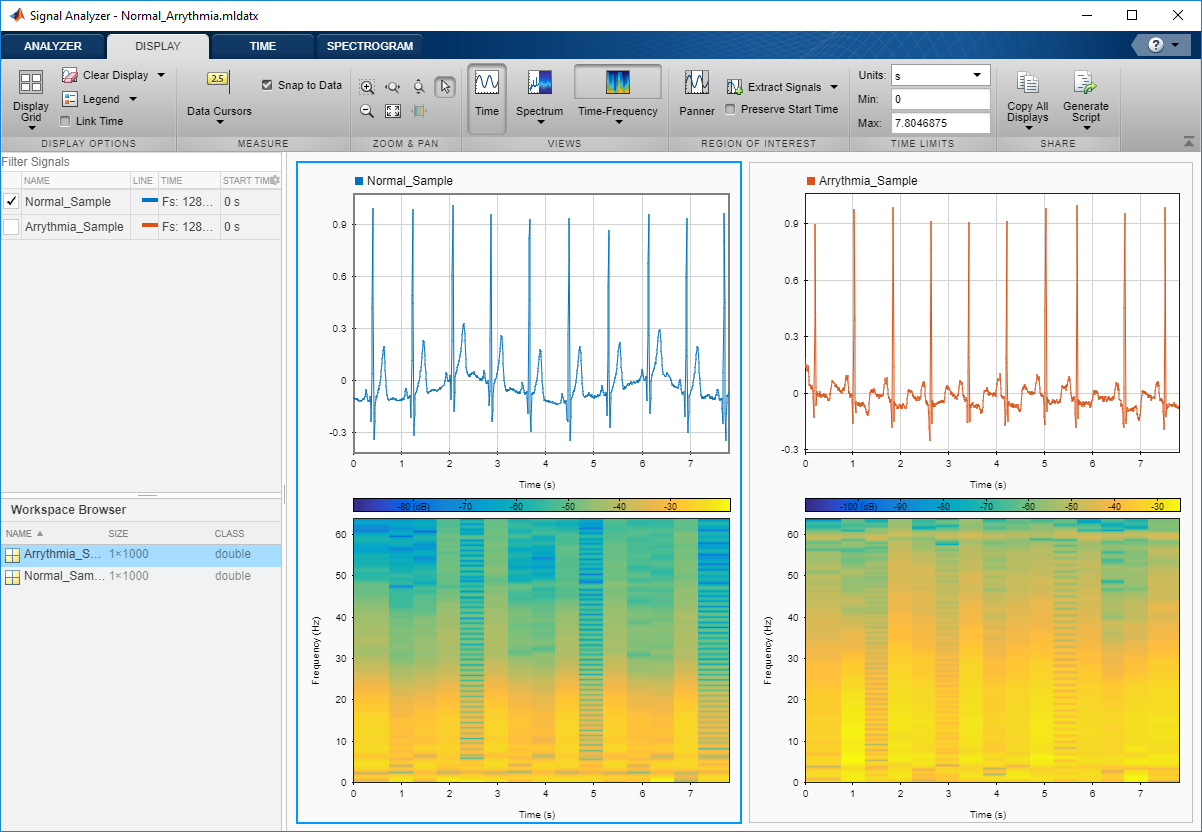

### 传统时频分析方法的挑战

使用传统的时间和频率分析可能会导致沿时间或频率的信号分辨率差。这是我们要解决的问题。

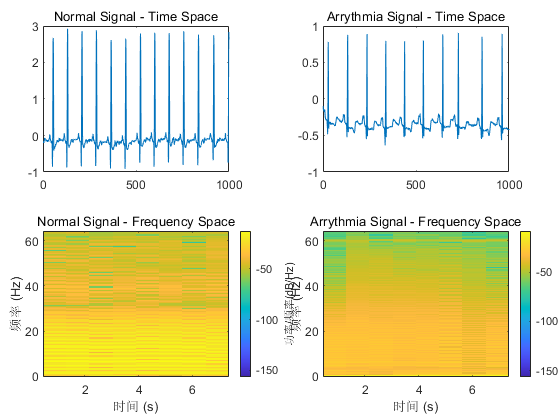

Normal_Sample_Class_I = ECGData.Data(find(ECGData.Labels=="NSR",1),1:1000);
Arrythmia_Sample_Class_II = ECGData.Data(find(ECGData.Labels=="ARR",1),1:1000);

clf
tiledlayout(2, 2, "Padding", "compact")
nexttile
plot(Normal_Sample_Class_I)
title('Normal Signal - Time Space')

nexttile
plot(Arrythmia_Sample_Class_II)
title('Arrythmia Signal - Time Space')

nexttile
spectrogram(Normal_Sample_Class_I, [], [], [], Fs, 'yaxis');
title('Normal Signal - Frequency Space')

nexttile
spectrogram(Arrythmia_Sample_Class_II, [], [], [], Fs, 'yaxis');
title('Arrythmia Signal - Frequency Space')

请注意，虽然信号有不同的含义，但传统的时频分析无助于识别两个信号之间的差异。

### 基于小波的时频分析

当你处理真实世界的信号时，这些信号具有不同尺度的特征（如ECG）。在时间上定位频谱内容是很重要的，因为这可以为您的信号处理洞察更多的信息。

连续小波变换可以帮助您获得信号清晰的时频表示，而无需指定任何参数，如窗口大小等。 

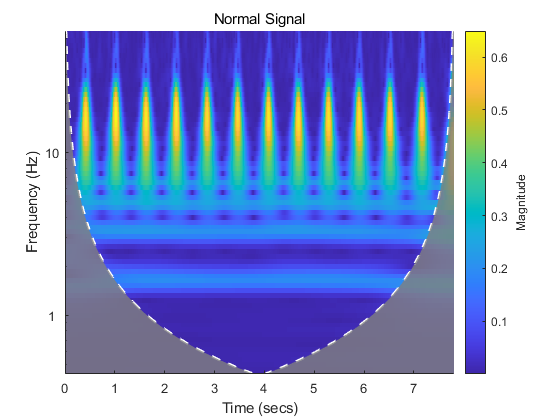

clf
cwt(Normal_Sample_Class_I, Fs)
title('Normal Signal')

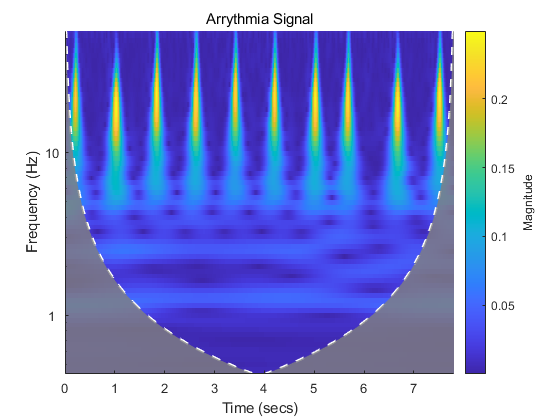


clf
cwt(Arrythmia_Sample_Class_II, Fs)
title('Arrythmia Signal')

请注意，小波变换是如何增强频谱细节的。例如，  

- 峰值分明

- 黄条线的不规则分布使我们可以区分了心律失常信号和正常信号

- 在心律失常表现的下半部分有一些活动，而正常信号没有

**我们可以将这些表示保存为图像并训练预配置的卷积神经网络。**

## **II. 生成小波时频表示**

### **创建一个**滤波器组

如果我们要对多个信号计算小波变换，则使用预先计算的滤波器组可以大大加快该过程。

sig = ECGData.Data(1,:);
signalLength = length(sig);
fb = cwtfilterbank('SignalLength', signalLength, 'SamplingFrequency', Fs)

fb =   cwtfilterbank - 属性:

      VoicesPerOctave: 10
              Wavelet: 'morse'
    SamplingFrequency: 128
       SamplingPeriod: []
         PeriodLimits: []
         SignalLength: 65536
      FrequencyLimits: []
        TimeBandwidth: 60
    WaveletParameters: []
             Boundary: 'reflection'


### 计算小波变换 

[wt, f] = fb.wt(sig);

#### **生成所有信号的时频可视化**

每个类别的图像将位于其自己的子目录中。如果图像已经生成，将忽略PrepareSignalData_cn处理。

if ~isfolder(fullfile(pwd, "data","CWT"))
    cats = unique(ECGData.Labels);
    for ii = 1:length(cats)
        mkdir(fullfile(pwd, "data", "CWT", cats{ii}))
    end
    alreadymade = false;
else
    try
        allImages = imageDatastore('data\',...
            'IncludeSubfolders', true, ...
            'LabelSource', 'foldernames');
        alreadymade = numel(allImages.Files)== size(ECGData.Data,1);
    catch
        alreadymade = false;
    end
end

if ~alreadymade
    PrepareSignalData_cn
end

打开 [`PrepareSignalData_cn.mlx`](matlab:edit('PrepareSignalData_cn.mlx');) 文件，以获得详细信息.

### 将时频表示图像分为训练集和测试集

`imageDatastore` 指向已标记数据的目录，并将自动创建训练和测试集。 图像数据存储区可以直接传递到神经网络训练功能中。 `readFcn` 确保图像尺寸符合第一输入层尺寸要求。

readFcn = @(imagefilename)imresize(imread(imagefilename), [227 227]);
allImages = imageDatastore(fullfile(pwd,"data", "CWT"), ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', ...
    'ReadFcn', readFcn);
[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');

## **III. 训练预训练的网络**

### **初始化网络 **

我们将加载经过预训练的 `alexnet` 网络.  这个网络可以通过附加功能管理器下载。为了减少网络能区分的种类，我们仅对最后几层进行重新训。我们用新的 `fullyConnectedLayer `和新的 `classificationLayer `替换它们。

alex = alexnet;
layers = alex.Layers;
layers(23) = fullyConnectedLayer(3);
layers(25) = classificationLayer;

您还可以通过[Deep Network Designer](https://www.mathworks.com/help/releases/R2019a/deeplearning/ref/deepnetworkdesigner-app.html) App 以图形方式执行此操作。

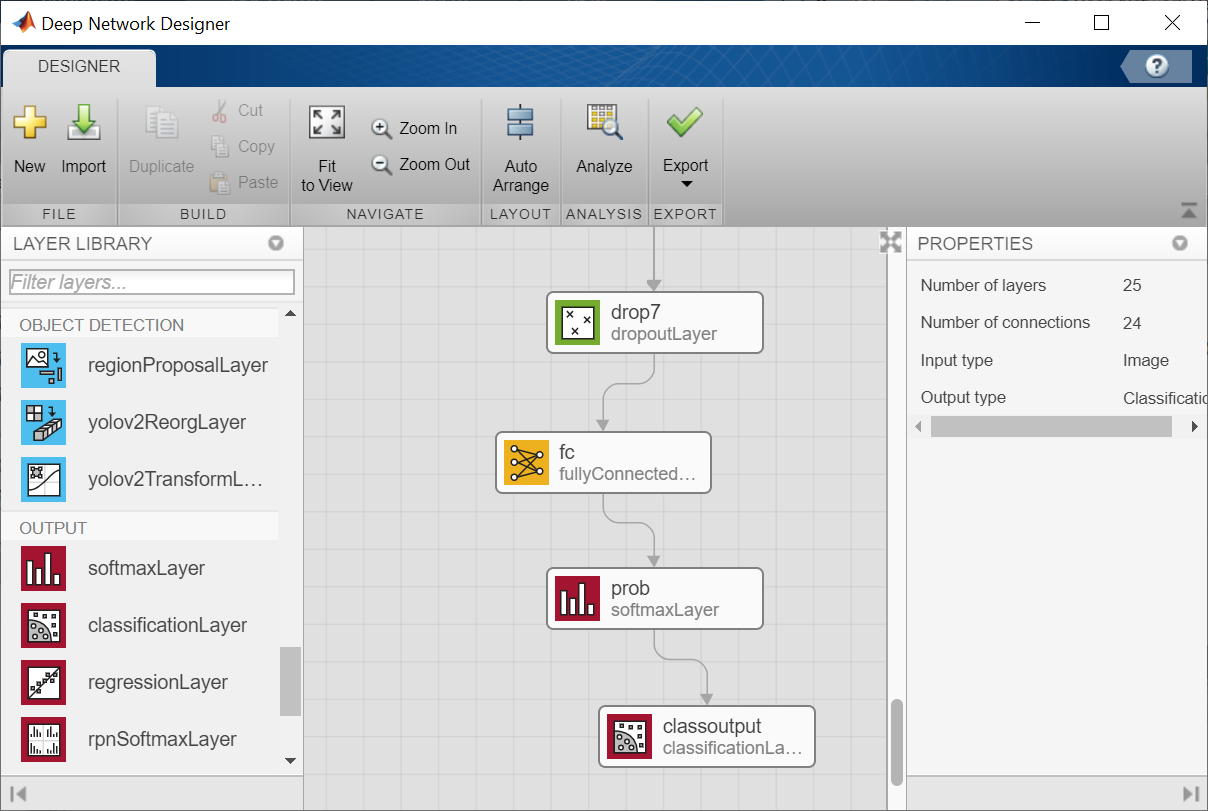

### **训练网络**

重新训练网络。 

在单 CPU 上训练。
正在初始化输入数据归一化。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　３０．００％　｜　　２．３６３４　｜　１．００００ｅ－０４　｜


｜　　　４　｜　　　５０　｜　　　　　００：００：４５　｜　　１００．００％　｜　　０．１０３４　｜　１．００００ｅ－０４　｜


｜　　　８　｜　　１００　｜　　　　　００：０１：３５　｜　　１００．００％　｜　　０．００１３　｜　１．００００ｅ－０４　｜


｜　　１２　｜　　１５０　｜　　　　　００：０２：３２　｜　　１００．００％　｜　　０．０１５２　｜　１．００００ｅ－０４　｜


｜　　１２　｜　　１５６　｜　　　　　００：０２：３９　｜　　１００．００％　｜　　０．００６９　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


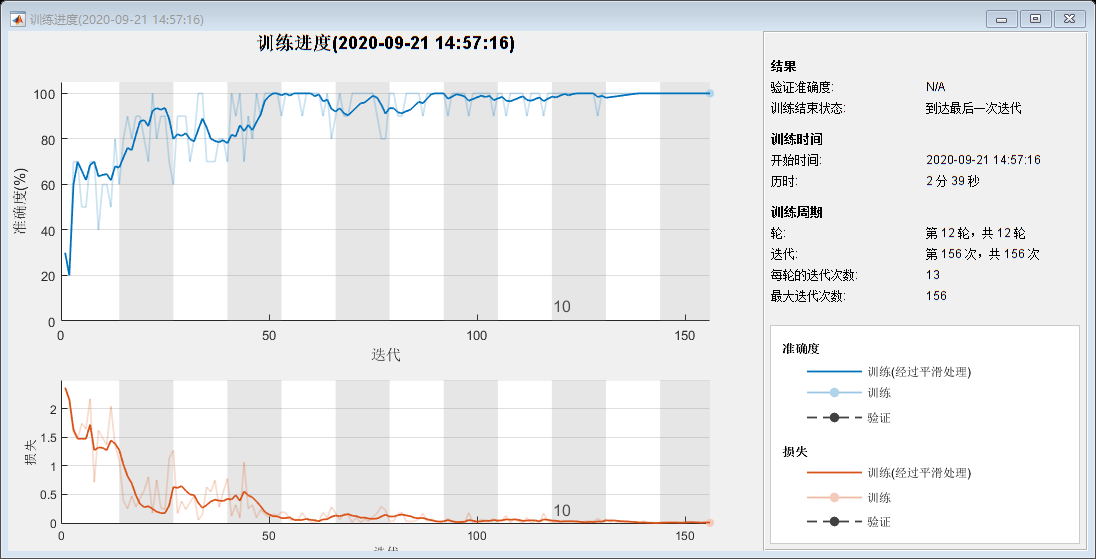

retrain = true;
 
if retrain
    opts = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.0001, ...
        'MaxEpochs', 12, ...
        'MiniBatchSize', 10, ...
        'Plots', 'training-progress');
    ECGNet = trainNetwork(trainingImages, layers, opts);
else

 [*查看训练的视频*](matlab:system('training.mp4');)*。*  

导入已经训练好的网络。这个网络需要通过训练获得。

    load(fullfile(pwd, "data", "ECGNet.mat"))
end

## **评价训练的模型**

在测试图像集上使用经过训练的模型，并显示混淆矩阵。

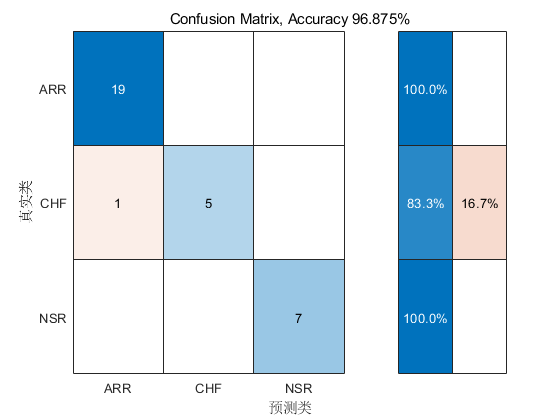

predictedLabels  = classify(ECGNet, testImages);
accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);

clf

cm = confusionchart(testImages.Labels, predictedLabels, ...
    "Title", "Confusion Matrix, Accuracy " + accuracy*100 + "%", ...
    "RowSummary", "row-normalized");

## 总结

我们已经看到了如何生成清晰的时频表示并定制/利用现有的深层网络来构建信号分类器。 仅需两行代码，您就可以为现实世界的信号生成清晰的时频表示，并将其用于使用深度网络构建分类器。

*Copyright 2020 The MathWorks, Inc.*